clear
tic
%% Datos de entrada para la función diseñada:
    % Intervalo de tiempo [a,b]
    a = 0; % (s)
    b = 1; % (s)
    % Número de masas horizontales
    N = 5;
    % Número de masas verticales
    M = 5;
    % Constante del resorte k, masa total M, longitud total L
    k =1; % (N/m)
    Mt = 1; % (kg)
    Lx = 2; % (m)
    Ly = 1; % (m)
    % Incremento
    h=0.1; % (s)

%% Parametros auxiliares
Lx0 = Lx/(N-1); % Longitud individual de cada resorte horizontal
Ly0 = Ly/(M-1); % Longitud individual de cada resorte vertical
x = cell(N,M);
y = cell(N,M);

%% Procedimiento
for j=1:M
    [t, z, Vz] = SEDO_red1D(a,b,N,k,Mt,Lx,h);
    for i=1:N
        x{i,j} = z(:,i);
    end
end

for i=1:N
    [t, z, Vz] = SEDO_red1D(a,b,M,k,Mt,Ly,h);
    for j=1:M
        y{i,j} = z(:,j);
    end
end

toc

Elapsed time is 798.773066 seconds.


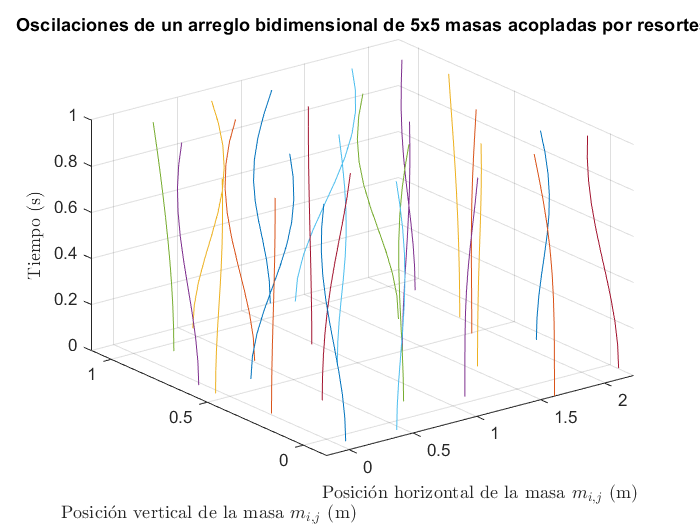

%% Transformación de la deformación w a coordenada posición z
for i=1:N
    for j=1:M
        plot3(x{i,j},y{i,j},t)
        hold on
    end
end
hold off
grid on
xlabel("Posici\'{o}n horizontal de la masa $m_{i,j}$ (m)",'Interpreter',"latex");
ylabel("Posici\'{o}n vertical de la masa $m_{i,j}$ (m)",'Interpreter',"latex");
zlabel('Tiempo (s)','Interpreter',"latex");
title(['Oscilaciones de un arreglo bidimensional de ',num2str(N),'x',num2str(M),' masas acopladas por resortes'])